# Figure 4

Network analysis for the iron interaction network

This need to be run first

## Figure1a


clear
clc

color_3classes=[0,153,62;
    242,150,0;
    195,13,35]/255;

%addpath('./Tools/')
datapath_mat='./data/outputrec.mat';
raw=load(datapath_mat);
outputrec=raw.outputrec;
clear raw;

colorpath='./data/colorcode_new.csv';

%Input the habitant information
habitantinfor='./data/1928strain_country_infor_1.xlsx';
hab_raw=importdata(habitantinfor);

outputrec.unistrains.unihabitants={'human','plant','soil','water','unknown','others'};
for i=1:length(outputrec.unistrains.name)
    strtemp=outputrec.unistrains.name{i};
    uniname=strtemp;
    loc_inhab=find(strcmp(hab_raw(:,1),uniname));
    if ~isempty(loc_inhab)
        outputrec.unistrains.habitant{i,1}=hab_raw{loc_inhab,2};
        outputrec.unistrains.habitant_id(i,1)=find(strcmp(outputrec.unistrains.unihabitants,outputrec.unistrains.habitant{i,1}));
    else
        error('err')
    end
end
%%%%% analyze each behavior's habitant
tabulate(outputrec.unistrains.habitant)

    Value    Count   Percent
    water      124      6.43%
    human      409     21.21%
   others      137      7.11%
  unknown      762     39.52%
     soil      262     13.59%
    plant      234     12.14%



for b=1:size(outputrec.unibehaviors,1)
    strainlist_thisbehave=find(outputrec.unistrains.behav_id==b);

    hablist=outputrec.unistrains.habitant_id(strainlist_thisbehave);
    for j=1:length(outputrec.unistrains.unihabitants)
        outputrec.unibehavior_habitantcomp(b,j)=sum(hablist==j);
    end
end
%%% how many rec groups are there, how many has colors, and how many has selfreceptors
maxrecgroup=max(outputrec.rec_groupid);
normbehav_habitantcomp=outputrec.unibehavior_habitantcomp./repmat(sum(outputrec.unibehavior_habitantcomp,2),1,size(outputrec.unibehavior_habitantcomp,2));
D = pdist(normbehav_habitantcomp);
% hab diffrence
hab_diff=squareform(D);
tree = linkage(D,'average');
leafOrder = optimalleaforder(tree,D);

% How many species are there
secondname=[];
for i=1:length(outputrec.unistrains.name)
    snamelist=strsplit(outputrec.unistrains.name{i},'_');
    secondname{i,1}=snamelist{2};
end

tabfreq=tabulate(secondname);
unique_secnames=tabfreq(:,1);
unique_sec_count=cell2mat(tabfreq(:,2));
[value,order]=sort(unique_sec_count,'descend');
unique_secnames=unique_secnames(order);
unique_sec_count=unique_sec_count(order);

for i=1:length(unique_secnames)
    if unique_sec_count(i)>5
        fprintf('%d\t%s\t%d\n',i,unique_secnames{i},unique_sec_count(i))
    end
end

1	sp	621
2	aeruginosa	554
3	fluorescens	135
4	syringae	116
5	putida	43
6	protegens	23
7	fragi	16
8	stutzeri	16
9	amygdali	15
10	chlororaphis	15
11	koreensis	15
12	psychrotolerans	14
13	brassicacearum	13
14	coronafaciens	11
15	oryzihabitans	11
16	frederiksbergensis	10
17	savastanoi	10
18	moraviensis	9
19	lundensis	8
20	mandelii	8
21	monteilii	8
22	asiatica	7
23	parafulva	7
24	poae	7
25	asplenii	6
26	helleri	6
27	mendocina	6
28	nitroreducens	6
29	synxantha	6



toremoverecgroup=find(outputrec.group_recnum_selfnum_purenum(:,2)==0);   
ratio_syn_v_rec=outputrec.group_recnum_selfnum_purenum(:,2)./outputrec.group_recnum_selfnum_purenum(:,1);


straintypecolor=[0,0.7,0;
    1,0.7,0;
    0.8,0,0];

goodlist={'fluorescens','putida','protegens','chlororaphis','synxantha','parafulva'};
badlist={'aeruginosa','syringae','stutzeri','amygdali','coronafaciens','oryzihabitans','savastanoi','mendocina'};
pathoornot=nan*zeros(sum(unique_sec_count>5),1);

for i=1:length(goodlist)
    pathoornot(strcmp(goodlist{i},unique_secnames))=0;
end
for i=1:length(badlist)
    pathoornot(strcmp(badlist{i},unique_secnames))=1;
end

colorcodes_pathornot=zeros(length(pathoornot),3);
for i=1:length(pathoornot)
    if pathoornot(i)==1
        colorcodes_pathornot(i,:)=[0.8,0,0];
    elseif pathoornot(i)==0
        colorcodes_pathornot(i,:)=[0,0.7,0.8];
    else
        colorcodes_pathornot(i,:)=[1,1,1]*0.5;
    end
end

%%%%%%%%%%%%%%%%%
outputcyto=0;
if outputcyto
    outputpath='./output/cytoscape_ironnet_byspecies_20231129_';
    spsizethresh=5;
    
    
    
    % output the network by behaviors
    netfid=fopen([outputpath,'network.csv'],'w+');
    fprintf(netfid,'source,target,isproduce,edgesize,edgecolor,species\n');
    
    for x=2:length(unique_secnames)
        spname=unique_secnames{x};
        slist=find(strcmp(secondname,spname));
        if length(slist)>spsizethresh
            behaveid_involved=unique(outputrec.unistrains.behav_id(slist));
            sid_involved=setdiff(unique(outputrec.unibehaviors(behaveid_involved,:)),0);
            
            % behaviors
            for k=1:length(behaveid_involved)
                b=behaveid_involved(k);
                sidgroup=outputrec.unibehaviors(b,1);
                recgroups=outputrec.unibehaviors(b,2:end);
                recgroups=recgroups(recgroups>0);
                
                if length(recgroups)>0
                    behav_size=sum(outputrec.unistrains.behav_id(slist)==b);
                    
                    % strains produce siderophore
                    if sidgroup>0
                        edgecolorstr= rgb2hex([0,0,0]);%outputrec.hexcolor{sidgroup};% defined the siderophore related
                        fprintf(netfid,'%s,%s,1,%d,%s,%s\n',[outputrec.unibehav_name{b},'(',spname,')'],[outputrec.groupname{sidgroup},'(',spname,')'],behav_size,edgecolorstr,spname);
                    end
                    % siderophore being utilized by...
                    for r=1:length(recgroups)
                        rid=recgroups(r);
                        if ~ismember(rid,toremoverecgroup)
                            edgecolorstr= outputrec.hexcolor{rid};% defined the siderophore related
                            fprintf(netfid,'%s,%s,0,%d,%s,%s\n',[outputrec.groupname{rid},'(',spname,')'],[outputrec.unibehav_name{b},'(',spname,')'],1,edgecolorstr,spname);
                        end
                    end
                    
                    
                    
                    
                end
                
            end
            
        end
    end
    
    fclose(netfid);
    
    % output the node properties
    nodefid=fopen([outputpath,'nodespro.csv'],'w+');
    fprintf(nodefid,['nodename,issid,nodesize,straintype,color,species,behav\n']);
    % siderophore groups
    
    for x=2:length(unique_secnames)
        spname=unique_secnames{x};
        slist=find(strcmp(secondname,spname));
        if length(slist)>spsizethresh
            behaveid_involved=unique(outputrec.unistrains.behav_id(slist));
            sid_involved=setdiff(unique(outputrec.unibehaviors(behaveid_involved,:)),0);
            
            % siderophores
            for i=1:length(sid_involved)
                r=sid_involved(i);
                behavstr=num2str(r);
                if ~ismember(r,toremoverecgroup)
                    % size: how many strains producing this one
                    colorstr=outputrec.hexcolor{r};
                    producernum=sum(outputrec.unistrains.behavior(slist,1)==r);
                    fprintf(nodefid,'%s,1,%d,nan,%s,%s,%s\n',[outputrec.groupname{r},'(',spname,')'],producernum,colorstr,spname,behavstr);
                end
            end% for i=1:length(sid_involved)
            
            % behaviors
            for k=1:length(behaveid_involved)
                b=behaveid_involved(k);
                sidgroup=outputrec.unibehaviors(b,1);
                recgroups=outputrec.unibehaviors(b,2:end);
                recgroups=setdiff(recgroups(recgroups>0),toremoverecgroup);
                
                strains_thisbehave=slist(outputrec.unistrains.behav_id(slist)==b);
                
                if length(recgroups)>0
                    % color by habitants
                    habs=outputrec.unistrains.habitant_id(strains_thisbehave,:);
                    hablist=zeros(1,length(outputrec.unistrains.unihabitants));
                    for j=1:length(outputrec.unistrains.unihabitants)
                        hablist(j)=sum(habs==j);
                    end
                    hablist=hablist/sum(hablist);
                    
                    %{'human','plant','soil','water','unknown','others'};
                    habcolor=[1,0,0;
                        0,1,0;
                        1,0.75,0; % socil
                        0,0,1;
                        0,0,0;
                        1,1,1];
                    colorstr=rgb2hex(hablist*habcolor);
                    
                    straintype=outputrec.unibehav_type(b);
                    %colorstr='nan';%rgb2hex(color_3classes(straintype,:));
                    
                    behavstr=[num2str(sidgroup),'|',strjoin(strsplit(num2str(recgroups)),';')];
                    fprintf(nodefid,'%s,0,%d,%d,%s,%s,%s\n',[outputrec.unibehav_name{b},'(',spname,')'],length(strains_thisbehave),straintype,colorstr,spname,behavstr);
                end
                
            end
            
        end %if length(slist)>spsizethresh
        
        
        
    end%  for x=1:length(unique_secnames)
    
    
    fclose(nodefid);
    
end



## Figure 4b：multi-rec producer%

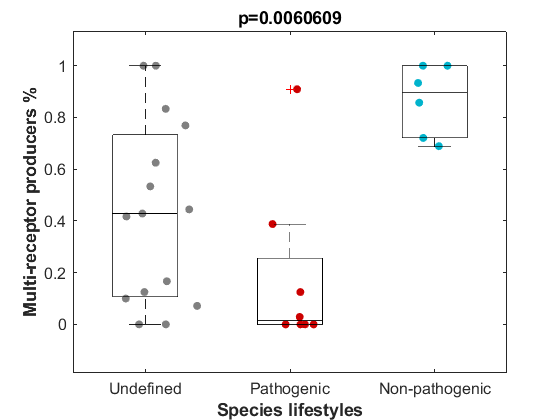


% syn/rec ratio by species
spsizethresh=5;
secname_synrecratio_produce_uptake=nan*zeros(length(unique_secnames),1); %unique_sec_count
pure_partial_cheaterratio=nan*zeros(length(unique_secnames),3); %unique_sec_count
behavior_diversity=nan*zeros(length(unique_secnames),1);
siderophore_diversity_whole_synrec=nan*zeros(length(unique_secnames),2);

% load whether they are pathegons or not

for i=1:length(unique_secnames)
    spname=unique_secnames{i};
    slist=find(strcmp(secondname,spname));
    
    
    
    if length(slist)>spsizethresh
        
        behavfreq=tabulate(outputrec.unistrains.behav_id(slist));
        behavfreq(behavfreq(:,2)==0,:)=[];
        behavior_diversity(i,1)=Entropy(behavfreq(:,3)/100);
        
        
        behavmat=outputrec.unistrains.behavior(slist,:);
        
        sids=behavmat(:,1);
        sids=sids(sids>0);
        
        recs=behavmat(:,2:end);
        recs=recs(recs~=0);
        recs=recs(~ismember(recs,toremoverecgroup));
        
        if length(sids)>0
            sids_freq=tabulate(sids);
            sids_freq(sids_freq(:,2)==0,:)=[];
            siderophore_diversity_whole_synrec(i,4)=size(sids_freq(:,1),1);
            secname_synrecratio_produce_uptake(i,1)=sum(sids_freq(:,3)/100.*ratio_syn_v_rec(sids_freq(:,1)));
            
            %%%%%
            % siderophore diversity
            siderophore_diversity_whole_synrec(i,2)=Entropy(sids_freq(:,3)/100);
            
        end
        
        rec_freq=tabulate(recs);
        rec_freq(rec_freq(:,2)==0,:)=[];
        secname_synrecratio_produce_uptake(i,2)=sum(rec_freq(:,3)/100.*ratio_syn_v_rec(rec_freq(:,1)));
        siderophore_diversity_whole_synrec(i,3)=Entropy(rec_freq(:,3)/100);
        
        tot_freq=tabulate([sids;recs]);
        tot_freq(tot_freq(:,2)==0,:)=[];
        siderophore_diversity_whole_synrec(i,1)=Entropy(tot_freq(:,3)/100);
        %%%%%%%
        recmat= outputrec.unistrains.recnum(slist);
        synmat=outputrec.unistrains.synnum(slist);
        strategycounts=[sum(synmat>0 & recmat==1),sum(synmat>0 & recmat>1),sum(synmat==0)];
        
        pure_partial_cheaterratio(i,:)=strategycounts/sum(strategycounts);
        
        %%%%%
        % behavior diversity
        
        
    end
end

data=pure_partial_cheaterratio(1:length(pathoornot),2);
figure,
hold on;
a=find(pathoornot==0);
b=find(pathoornot==1);
c=find(isnan(pathoornot));

    data_np=data(a);
    data_p=data(b);
    data_na=data(c);
    
    % Create a grouping indicator vector
    
    group1 = 1*ones(size(data_na));
    group2 = 2*ones(size(data_p));
    group3 = 3*ones(size(data_np));
    
    % Merge data
    allData = [data_na;data_p;data_np];
    allData_1 = [data_p;data_np];
    groups = [group1;group2;group3];
    groups_1 = [group2;group3];
    % Create a virtual x-coordinate
    groupSizes = [numel(data_na), numel(data_p), numel(data_np)];
    groupLabels = {'Undefined','Pathogenic','Non-pathogenic'};
    xLabels = repelem(groupLabels, groupSizes);
    xValues = repelem(1:numel(groupSizes), groupSizes);
    % Add raw data points to scatter plot
    x=xValues + 0.1*randn(size(xValues));
    y=allData;
    colors=[0.5,0.5,0.5;0.8,0,0;0,0.7,0.8];
    for i = 1:3
        idx = groups == i;
        scatter(x(idx), y(idx), [], colors(i,:), 'filled');
    end
  
    
    hold on;
    % Draw box plot
    boxplot(allData, xValues, 'Labels', xLabels,"Colors","k");
    
    % Perform analysis of variance
    [p, tbl, stats] = kruskalwallis(allData_1, groups_1,'off');
    
    % Set graphic properties
    xlabel('Species lifestyles','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel('Multi-receptor producers %','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    title(['p=',num2str(p)],'FontName', 'Arial','FontSize', 16, 'FontWeight', 'bold')
    % Set the axis font
    set(gca, 'FontName', 'Arial', 'FontSize', 12);

## Figure4c: number of the functional siderophore group

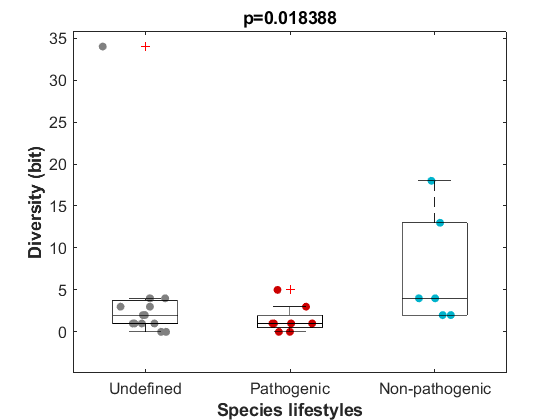

data=siderophore_diversity_whole_synrec(1:length(pathoornot),4);

figure,
hold on;
a=find(pathoornot==0);
b=find(pathoornot==1);
c=find(isnan(pathoornot));

    data_np=data(a);
    data_p=data(b);
    data_na=data(c);
    
    
    group1 = 1*ones(size(data_na));
    group2 = 2*ones(size(data_p));
    group3 = 3*ones(size(data_np));
  
    allData = [data_na;data_p;data_np];
    allData_1 = [data_p;data_np];
    groups = [group1;group2;group3];
    groups_1 = [group2;group3];
   
    groupSizes = [numel(data_na), numel(data_p), numel(data_np)];
    groupLabels = {'Undefined','Pathogenic','Non-pathogenic'};
    xLabels = repelem(groupLabels, groupSizes);
    xValues = repelem(1:numel(groupSizes), groupSizes);
   
    x=xValues + 0.1*randn(size(xValues));
    y=allData;
    colors=[0.5,0.5,0.5;0.8,0,0;0,0.7,0.8];
    for i = 1:3
        idx = groups == i;
        scatter(x(idx), y(idx), [], colors(i,:), 'filled');
    end
   
    
    hold on;
    
    boxplot(allData, xValues, 'Labels', xLabels,"Colors","k");
    
    
    [p, tbl, stats] = kruskalwallis(allData_1, groups_1,'off');
    
    
    xlabel('Species lifestyles','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel('Diversity (bit)','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    title(['p=',num2str(p)],'FontName', 'Arial','FontSize', 16, 'FontWeight', 'bold')
  
    set(gca, 'FontName', 'Arial', 'FontSize', 12);

## Figure4d: diversity 

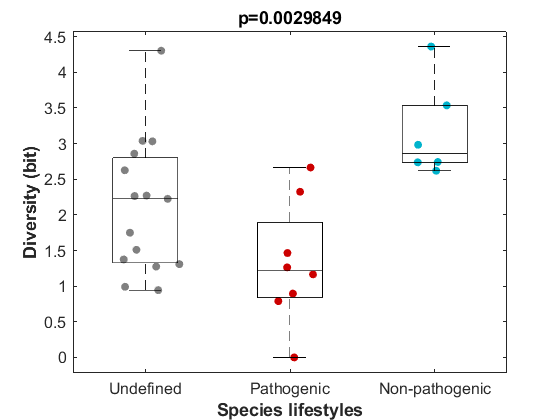


data=siderophore_diversity_whole_synrec(1:length(pathoornot),1);

figure,
hold on;
a=find(pathoornot==0);
b=find(pathoornot==1);
c=find(isnan(pathoornot));

    data_np=data(a);
    data_p=data(b);
    data_na=data(c);
    
   
    
    group1 = 1*ones(size(data_na));
    group2 = 2*ones(size(data_p));
    group3 = 3*ones(size(data_np));
    
   
    allData = [data_na;data_p;data_np];
    allData_1 = [data_p;data_np];
    groups = [group1;group2;group3];
    groups_1 = [group2;group3];
   
    groupSizes = [numel(data_na), numel(data_p), numel(data_np)];
    groupLabels = {'Undefined','Pathogenic','Non-pathogenic'};
    xLabels = repelem(groupLabels, groupSizes);
    xValues = repelem(1:numel(groupSizes), groupSizes);
   
    x=xValues + 0.1*randn(size(xValues));
    y=allData;
    colors=[0.5,0.5,0.5;0.8,0,0;0,0.7,0.8];
    for i = 1:3
        idx = groups == i;
        scatter(x(idx), y(idx), [], colors(i,:), 'filled');
    end
  
    
    
    hold on;
  
    boxplot(allData, xValues, 'Labels', xLabels,"Colors","k");
    
  
    [p, tbl, stats] = kruskalwallis(allData_1, groups_1,'off');
    
   
    xlabel('Species lifestyles','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel('Diversity (bit)','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    title(['p=',num2str(p)],'FontName', 'Arial','FontSize', 16, 'FontWeight', 'bold')
    
    set(gca, 'FontName', 'Arial', 'FontSize', 12);

## Figure4e Syn/Rec

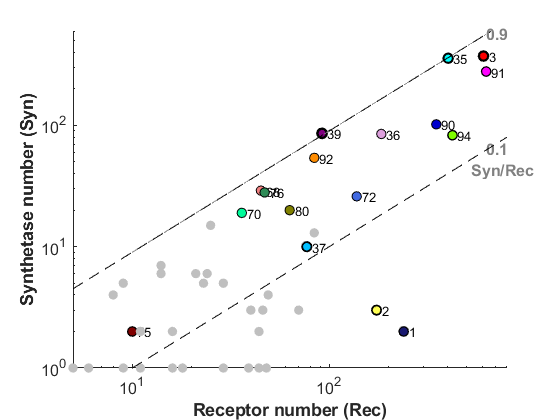

figure;
outputrec.group_recnum_selfnum_purenum;
xvalue=outputrec.group_recnum_selfnum_purenum(:,1);
yvalue=outputrec.group_recnum_selfnum_purenum(:,2);
for i=1:length(value)
    hold on;
    

    producerlist=find(outputrec.unistrains.behavior(:,1)==i);
    purenum=sum(outputrec.unistrains.recnum(producerlist)==1);
    fractionbypure=2*purenum/length(producerlist);

    if length(producerlist)>0
        ms=50;
        sh=scatter(xvalue(i),yvalue(i),ms,hex2rgb(outputrec.hexcolor{i}),'filled');
        if fractionbypure>0
            sh.MarkerEdgeColor=[0,0,0];%outputrec.edgecolor(i,:);
            sh.LineWidth=fractionbypure;
            if 1
                th=text(xvalue(i)*1.06,yvalue(i),num2str(i));
            end
        end
    end
end

xx1=10:max(xvalue);
yy1=xx1 .* 0.1;
yy2=xx1 .* 0.9;

line(xx1, yy1, 'Color', [0.5, 0.5, 0.5], 'LineStyle', '--');
text(max(xx1)+1,max(yy1)+1,'0.1',"Color",[0.5, 0.5, 0.5],'FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
line(xx1, yy2, 'Color', [0.5, 0.5, 0.5], 'LineStyle', '--');
text(max(xx1)+1,max(yy2)+1,'0.9',"Color",[0.5, 0.5, 0.5],'FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
text(max(xx1)-100,max(yy1)-20,'Syn/Rec',"Color",[0.5, 0.5, 0.5],'FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Receptor number (Rec)','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('Synthetase number (Syn)','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold')
set(gca, 'FontName', 'Arial', 'FontSize', 12);
set(gca,'xscale','log')
set(gca,'yscale','log')
minv=min([xvalue;yvalue]);
maxv=max([xvalue;yvalue]);
axis([minv maxv minv maxv])

minx=5;miny=1;
maxx=800;maxy=600;
xlim([minx maxx])
ylim([miny maxy]);
for ratio=[0.1,0.9]
    plot([minx,maxx],ratio*[minx,maxx],'-- k')
end

## Figure4f: Weighted Syn/Rec ratio

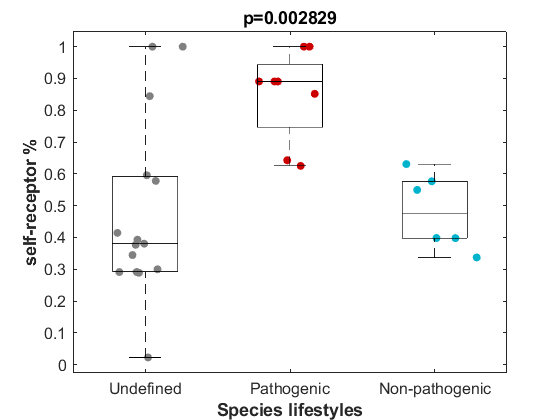

data=secname_synrecratio_produce_uptake(1:length(pathoornot),1);
data(isnan(data))=1;

figure,
hold on;
a=find(pathoornot==0);
b=find(pathoornot==1);
c=find(isnan(pathoornot));

    data_np=data(a);
    data_p=data(b);
    data_na=data(c);
    
    
    
    group1 = 1*ones(size(data_na));
    group2 = 2*ones(size(data_p));
    group3 = 3*ones(size(data_np));
    
    
    allData = [data_na;data_p;data_np];
    allData_1 = [data_p;data_np];
    groups = [group1;group2;group3];
    groups_1 = [group2;group3];
  
    groupSizes = [numel(data_na), numel(data_p), numel(data_np)];
    groupLabels = {'Undefined','Pathogenic','Non-pathogenic'};
    xLabels = repelem(groupLabels, groupSizes);
    xValues = repelem(1:numel(groupSizes), groupSizes);
    
    x=xValues + 0.1*randn(size(xValues));
    y=allData;
    colors=[0.5,0.5,0.5;0.8,0,0;0,0.7,0.8];
    for i = 1:3
        idx = groups == i;
        scatter(x(idx), y(idx), [], colors(i,:), 'filled');
    end
   
    
    
    hold on;
   
    boxplot(allData, xValues, 'Labels', xLabels,"Colors","k");
    
    
    [p, tbl, stats] = kruskalwallis(allData_1, groups_1,'off');
    
   
    xlabel('Species lifestyles','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel('self-receptor %','FontName', 'Arial', 'FontSize', 12, 'FontWeight', 'bold');
    title(['p=',num2str(p)],'FontName', 'Arial','FontSize', 16, 'FontWeight', 'bold')
  
    set(gca, 'FontName', 'Arial', 'FontSize', 12);

## Figure 4g 

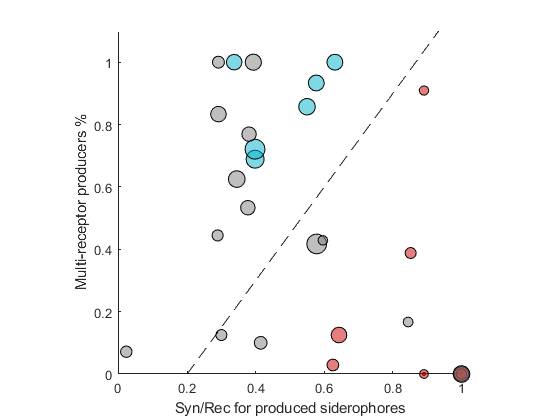


% syn/rec ratio by species
spsizethresh=5;
secname_synrecratio_produce_uptake=nan*zeros(length(unique_secnames),1); %unique_sec_count
pure_partial_cheaterratio=nan*zeros(length(unique_secnames),3); %unique_sec_count
behavior_diversity=nan*zeros(length(unique_secnames),1);
siderophore_diversity_whole_synrec=nan*zeros(length(unique_secnames),2);

% load whether they are pathegons or not

for i=1:length(unique_secnames)
    spname=unique_secnames{i};
    slist=find(strcmp(secondname,spname));
    
    
    
    if length(slist)>spsizethresh
        
        behavfreq=tabulate(outputrec.unistrains.behav_id(slist));
        behavfreq(behavfreq(:,2)==0,:)=[];
        behavior_diversity(i,1)=Entropy(behavfreq(:,3)/100);
        
        
        behavmat=outputrec.unistrains.behavior(slist,:);
        
        sids=behavmat(:,1);
        sids=sids(sids>0);
        
        recs=behavmat(:,2:end);
        recs=recs(recs~=0);
        recs=recs(~ismember(recs,toremoverecgroup));
        
        if length(sids)>0
            sids_freq=tabulate(sids);
            sids_freq(sids_freq(:,2)==0,:)=[];
            siderophore_diversity_whole_synrec(i,4)=size(sids_freq(:,1),1);
            secname_synrecratio_produce_uptake(i,1)=sum(sids_freq(:,3)/100.*ratio_syn_v_rec(sids_freq(:,1)));
            
            %%%%%
            % siderophore diversity
            siderophore_diversity_whole_synrec(i,2)=Entropy(sids_freq(:,3)/100);
            
        end
        
        rec_freq=tabulate(recs);
        rec_freq(rec_freq(:,2)==0,:)=[];
        secname_synrecratio_produce_uptake(i,2)=sum(rec_freq(:,3)/100.*ratio_syn_v_rec(rec_freq(:,1)));
        siderophore_diversity_whole_synrec(i,3)=Entropy(rec_freq(:,3)/100);
        
        tot_freq=tabulate([sids;recs]);
        tot_freq(tot_freq(:,2)==0,:)=[];
        siderophore_diversity_whole_synrec(i,1)=Entropy(tot_freq(:,3)/100);
        %%%%%%%
        recmat= outputrec.unistrains.recnum(slist);
        synmat=outputrec.unistrains.synnum(slist);
        strategycounts=[sum(synmat>0 & recmat==1),sum(synmat>0 & recmat>1),sum(synmat==0)];
        
        pure_partial_cheaterratio(i,:)=strategycounts/sum(strategycounts);

    end
end

x=secname_synrecratio_produce_uptake(1:length(pathoornot),1);
y=pure_partial_cheaterratio(1:length(pathoornot),2);
ms=5+50*siderophore_diversity_whole_synrec(1:length(pathoornot),1);


x(isnan(x))=1;
%
figure;
scatter(x,y,ms,colorcodes_pathornot,'filled', 'MarkerFaceAlpha', .5, 'MarkerEdgeColor', 'k');hold on;
%text(x,y+0.05,unique_secnames(1:length(pathoornot)));
%set(gca,'fontsize',20);
hold on;
xx1=0.2:0.01:1;
yy1=linspace(0, 1.2, 81);
line(xx1, yy1, 'Color', [0, 0, 0], 'LineStyle', '--');
xlabel('Syn/Rec for produced siderophores');
ylabel('Multi-receptor producers %')
axis square
ylim([0 1.1])